# Audio Modulation AM

## Lectura de Audio

Primero se leera un audio. Tener cuidado con las lecutras de audio ya que pueden ser de dos canales para leer un solo canal vea como se hace en el script de abajo. 

clear all;
[Sound,Fs]=audioread('Audios/seriously.wav'); 
Fs % numero de muestras por segundo 

Fs = 48000

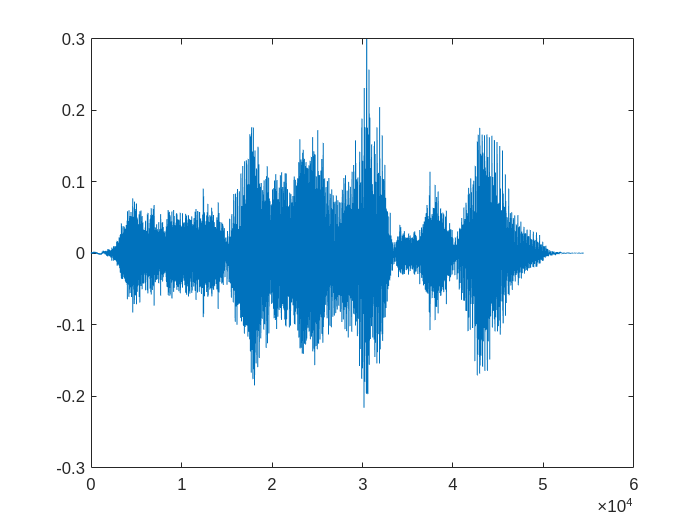

Sound = Sound(:,1); % Read one chann
plot(Sound);

%sound(Sound,Fs);

## Interpolacion y resampling

Se desea poner la FS a 64K $\frac{\mathrm{muestras}}{\sec }$ por lo que se tiene que hacer una interpolación.  Sin embargo las funciones de interpolacion solo aceptan enteros, por lo que primero se hace un downsampling y luego una interpolacion, para que quede en pares. SI es 48Khz hacemos downsampling a Y. Solo se toma solo el primer segundo por facilidad. Con eso tendremos nuestra señal de mensaje $m\left(t\right)$

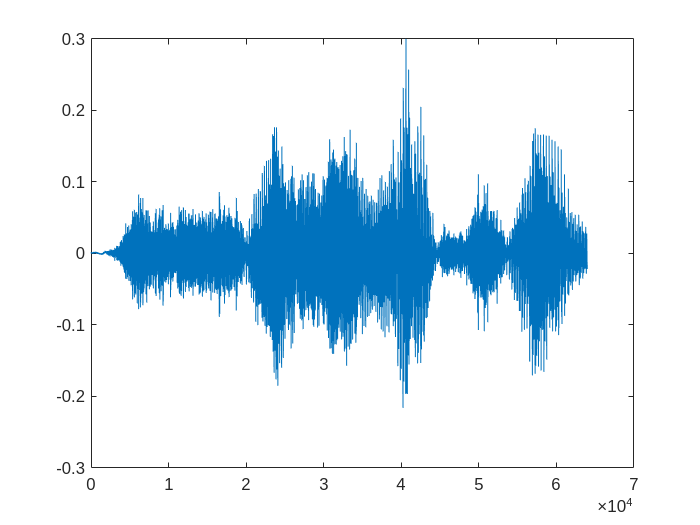

kps_64 =  64000;
Sound_interpolate = resample(Sound,kps_64,Fs); % Interpolacion
m_t = Sound_interpolate(1:(kps_64+1)); %cut one second final message signal
plot(m_t);

%sound(m_t,kps_64);

### Generacion de ejes Frequenciales y Temporales

Se realizara un eje de frequencia de -32K a 32K y como tenemos un segundo de tiempo de observacion, la resolucion es de 1. Recordad que el paso en frequencia y tiempo son inversos. 


$$t=\left\lbrack -\frac{t}{2}:\frac{1}{F_s }:\ldotp \frac{t}{2}\right\rbrack$$



$$f=\left\lbrack -\frac{f_s }{2}:T_{\mathrm{obs}} :\frac{f}{2}\right\rbrack$$


% El tiempo es muestreado con una resolucion de la longitud del eje frequencial
time = -.5:1/kps_64:.5; 
% La frequencia es muestreada con una resolucion de la longitud en tiempo
% De un rango de -Fs/2 a Fs/2
freq = -kps_64/2:1:kps_64/2;    

Portadora de 20khz para transmicion en AM

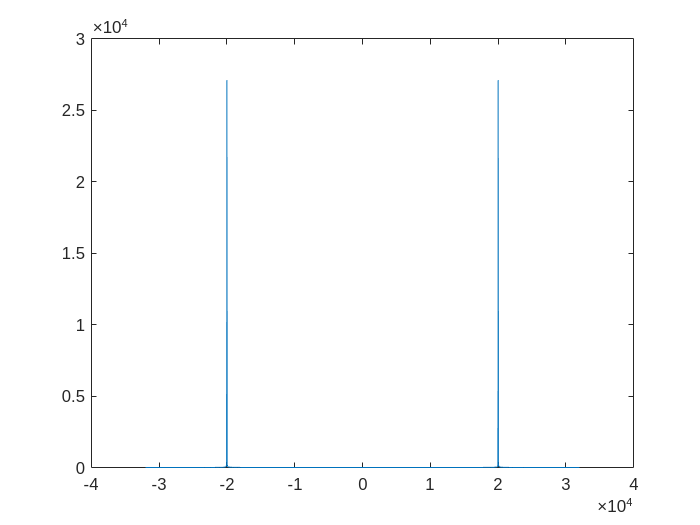

portadora = cos(2*pi*20e3*time); % portadora en 20Khz
plot(freq,abs(ttof(portadora)));

## Modulacion de AM

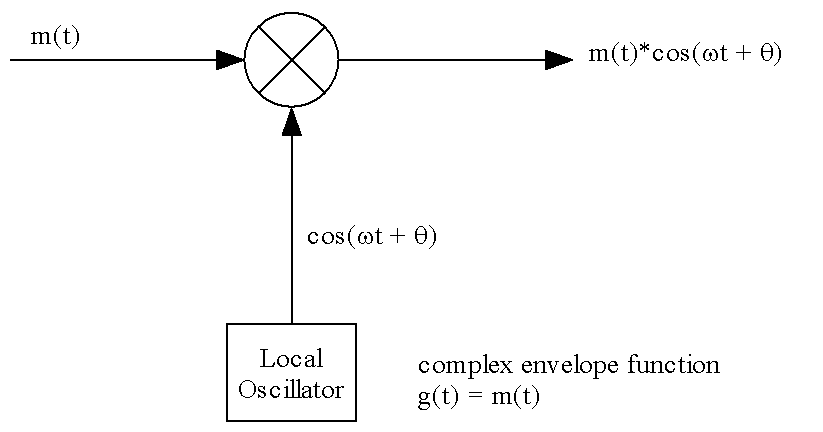

Con el diagrama de arriba podemos usar m(t) y multplicarlo por la portadora. Cuando grafiquemos el espectro veremos que la señal se ve centrada por la dos deltas del diagrama superior. 

Al multiplicarse la señal m(t) en tiempo se convoluciona en frecuencia. 


$$cos(\omega_o t)\rightarrow \frac{1}{2}[\delta[\omega-\omega_0]+\delta[\omega+\omega_0]$$


$m(t)\times cos(\omega_ct)$ en frecuencia es $M(\omega)*\frac{1}{2}[\delta[\omega-\omega_0]+\delta[\omega+\omega_0]]$ [[PAG ](https://uspas.fnal.gov/materials/11ODU/FourierTransformPairs.pdf)2]

- La señal en frequencia se convoluciona con dos deltas una a la izquierda y otra a la derecha. Y como son lineales se puede hacer individualmente cada una. 

- Cualquier señal convolucionada con una delta, es la misma funcion en la posicion de la delta. [[FORO](https://math.stackexchange.com/questions/1015498/convolution-with-delta-function)]


$$f(t)*\delta(t-a)=\int_{-\infty}^\infty f(x)\delta(x-a)\,dx=f(a)$$


        3. Por lo tanto tenemos el siguiente resultado con $M\left(\omega \right)$


$$M(\omega)*\frac{1}{2}[\delta[\omega-\omega_c]+\delta[\omega+\omega_c]]$$



$$\frac{1}{2}M(\omega-\omega_o)+\frac{1}{2}M(\omega+\omega_0)$$


    La señal queda desplada en frequencia $\omega_0$ tanto para la izquierda y derecha 

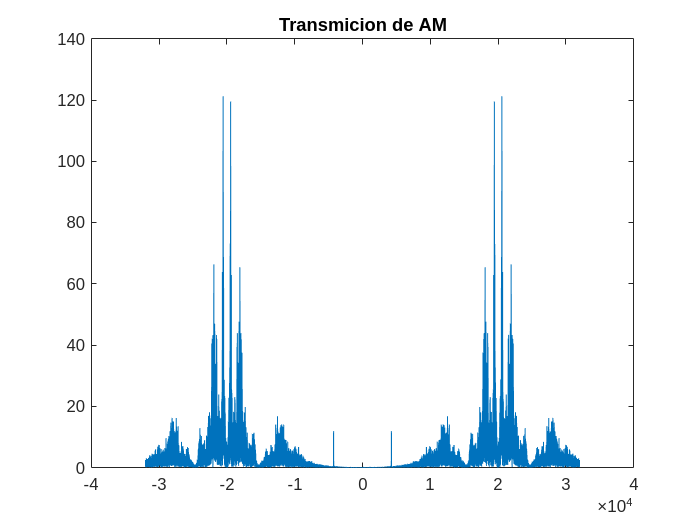

sig_mod = portadora.*m_t'; % en frecuencia es la convolucion 
plot(freq,abs(ttof(sig_mod))) % grafica de la señal modulada
title('Transmicion de AM');

NOTA: Se gasta mas ancho de bando por que la porque de las frequencias negativas ahora son visibles en un canal de transmición. 

## Demodulacion de AM

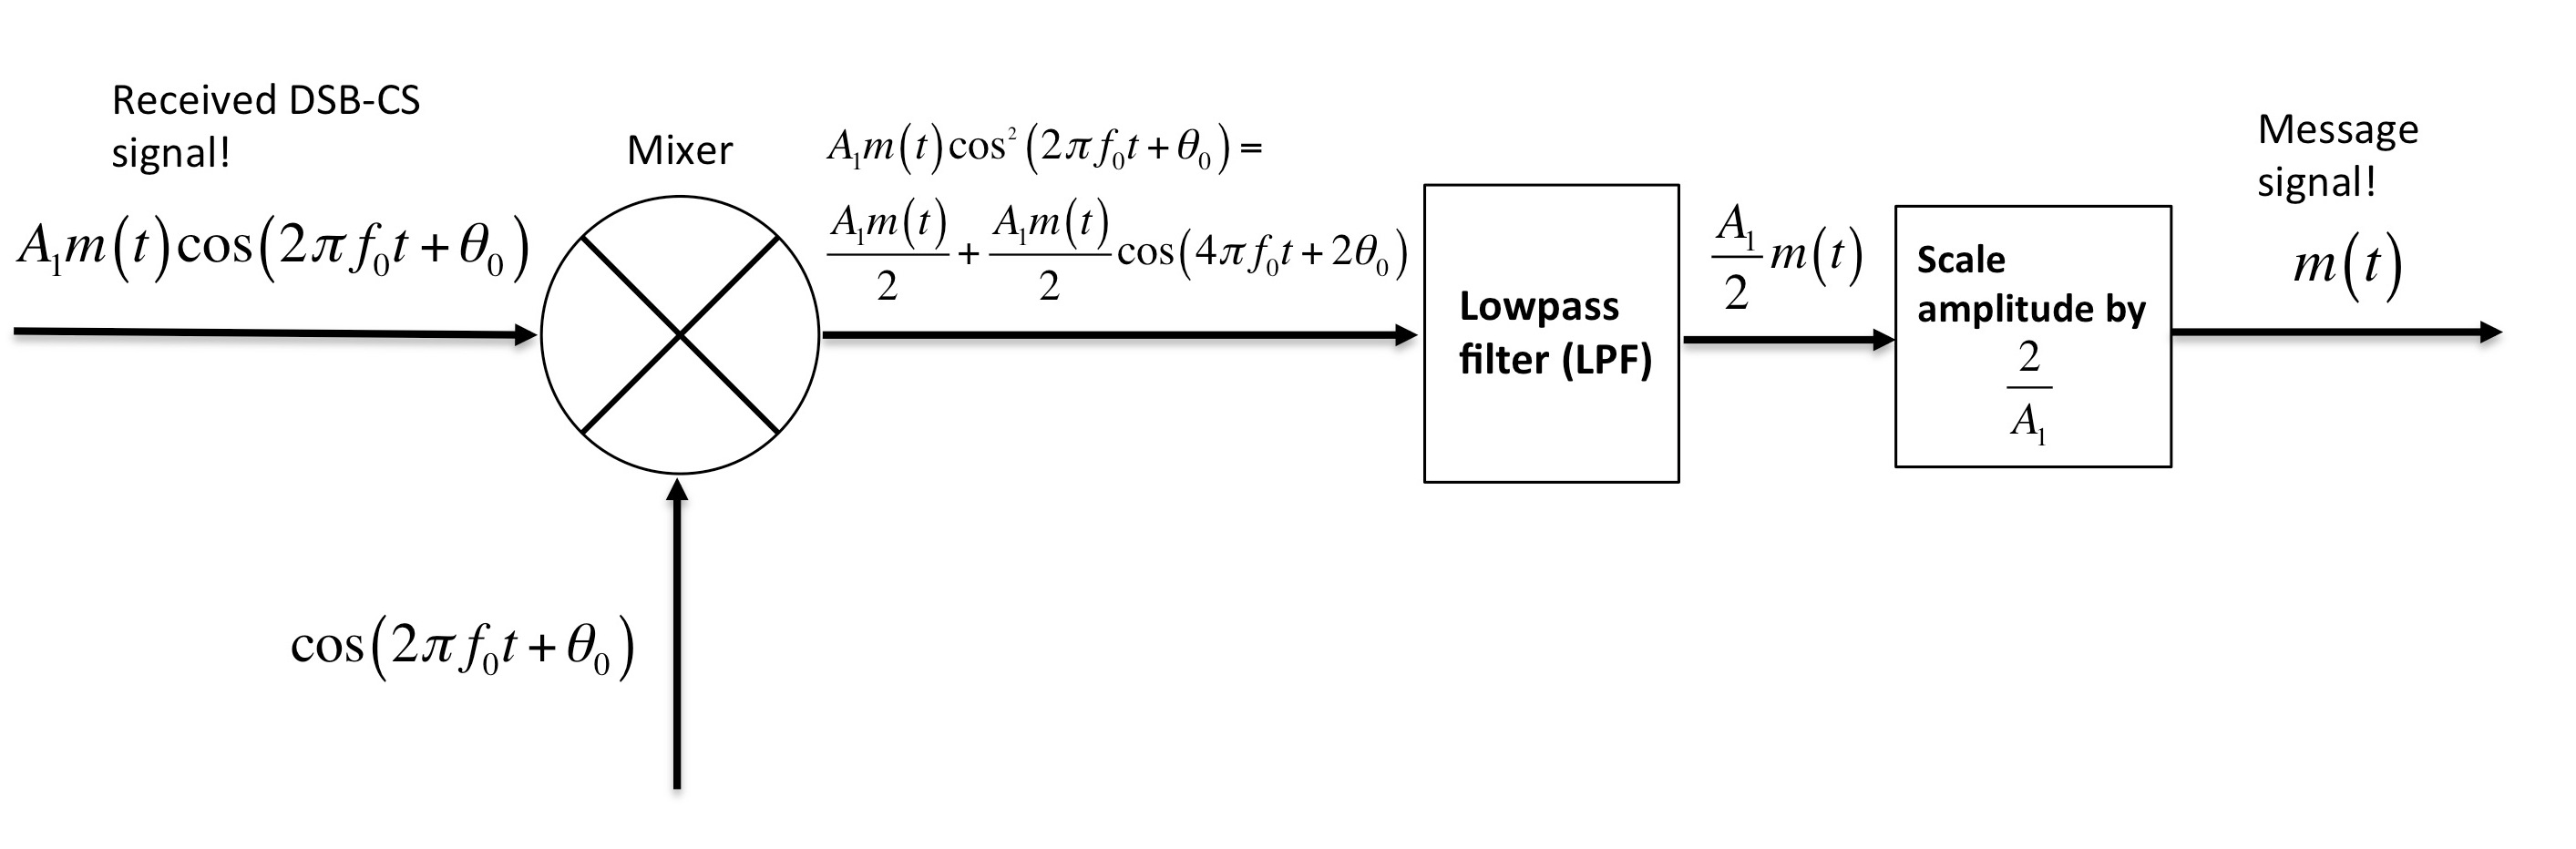

- La señal de recepección es $m(t)cos(w_ct)$

- La señal demodulada es $m(t)cos(w_ct)cos(w_ct)=m(t)cos^2(w_ct)$

- Existe una propiedad trigonometrica [[PAG 4](https://uspas.fnal.gov/materials/11ODU/FourierTransformPairs.pdf)] $cos^2(x) \rightarrow \frac{1}{2}[1+cos(2x)]$

- Por lo tanto la señal queda expandida de esta forma $\frac{m(t)}{2} + m(t) cos(2w_ct)$

- Su transfromada de fourier $\frac{M(\omega)}{2}+\frac{1}{2}[\frac{1}{2}M(\omega-2\omega_c)+\frac{1}{2}M(\omega+2\omega_c)]$

    
$$\frac{M(\omega)}{2}+[\frac{1}{4}M(\omega-2\omega_c)+\frac{1}{4}M(\omega+2\omega_c)]$$


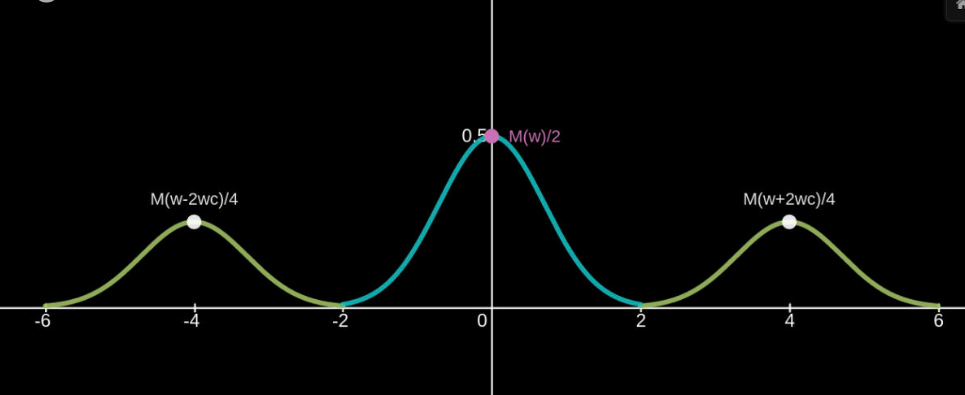

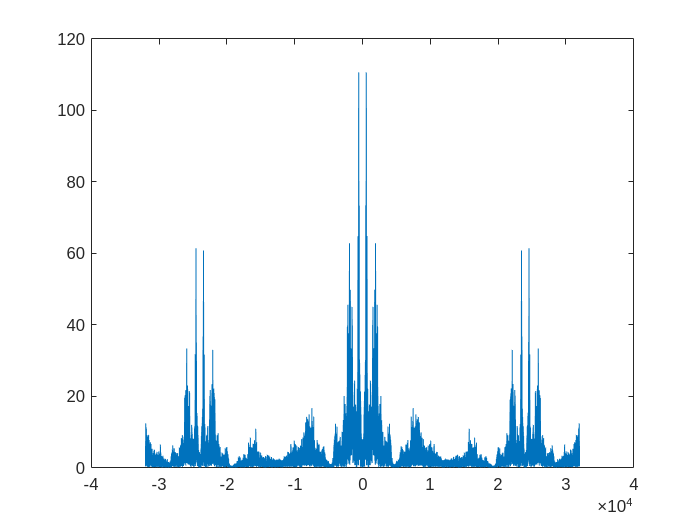

sig_recover = sig_mod.*portadora;
plot(freq,abs(ttof(sig_recover)))

La portadora esta en 20khz, por lo tanto las señales laterales deberia estar centrada en $\pm$40khz. Esto se puede inferir por la ultima ecuacion calculada. Donde tenemos la señal en medio y las otras dos señales en $2\omega_c =40$.

    
$$\frac{M(\omega)}{2}+[\frac{1}{4}M(\omega-2\omega_c)+\frac{1}{4}M(\omega+2\omega_c)]$$


#### **Sin embargo vemos que la señal no esta centrada en 40 Khz si no en 24kHz ¿Por que?!!!**

Lo que sucede es que la señal se encuentra fuera del rango de frecuencia libre de alias. Dado que nuestro rango solo es valido para [-32Khz,32Khz] . Para tener mas claro el problema hay que descomponer la ecuacion en sus componentes de desplazamiento.

[Graphica Interactiva](https://www.desmos.com/calculator/1ldez5yj7t)

Desplazamiento derecha 

    
$$\frac{1}{4}M(\omega-2\omega_c)$$


Desplazamiento Izquierda 

    
$$\frac{1}{4}M(\omega+2\omega_c)$$


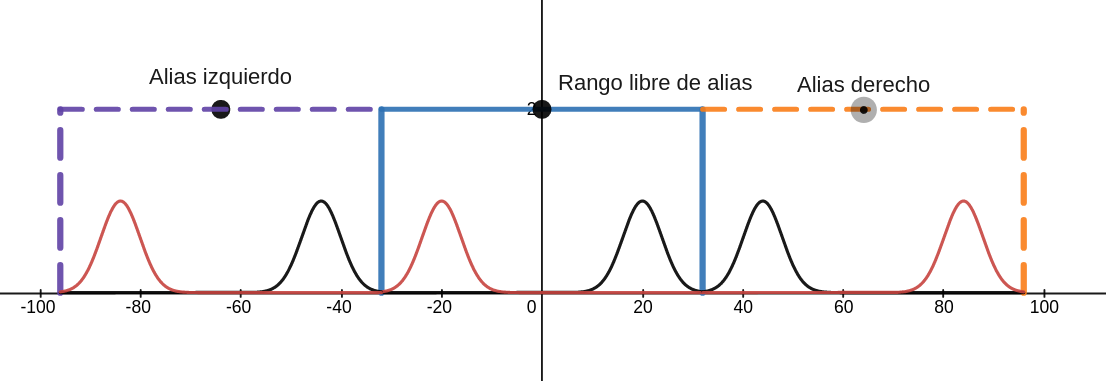

### **Desplazamiento derecha **

Con el desplazamiento derecha todas las frecuencias seran desplazadas 40 Khz a la derecha. Incluyendo las que estan en la region de alizas izquierdo.

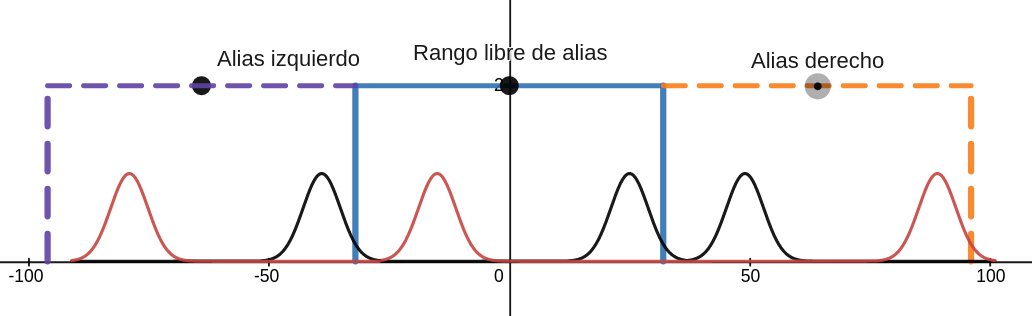

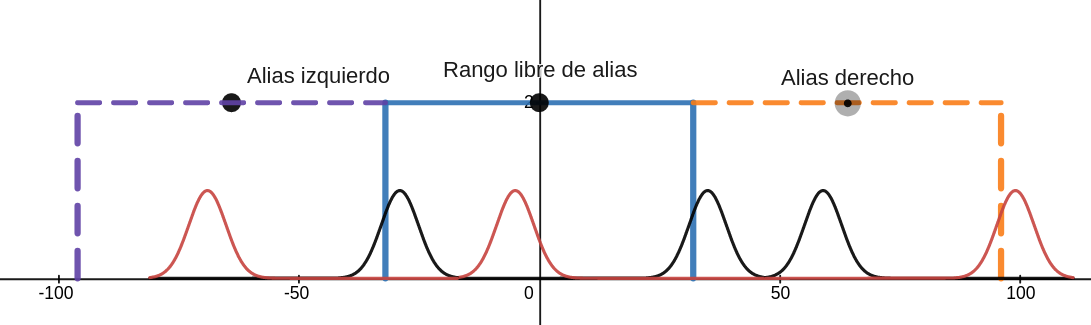

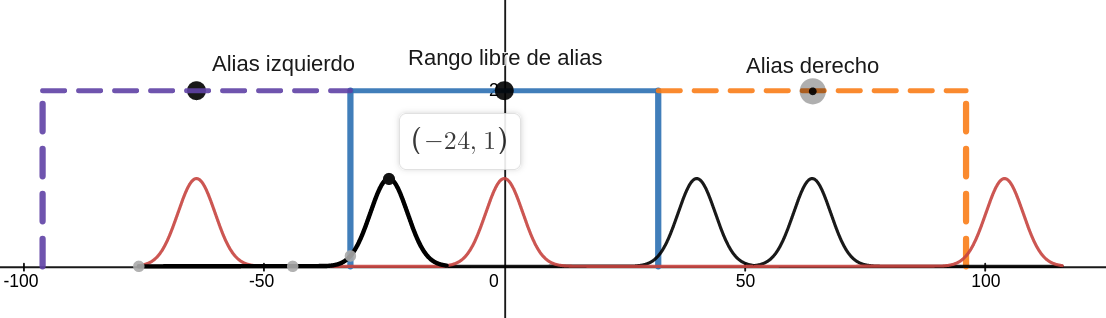

La señal de la izquierda queda centrada en -24kHz

**Desplazamiento Izquierda **

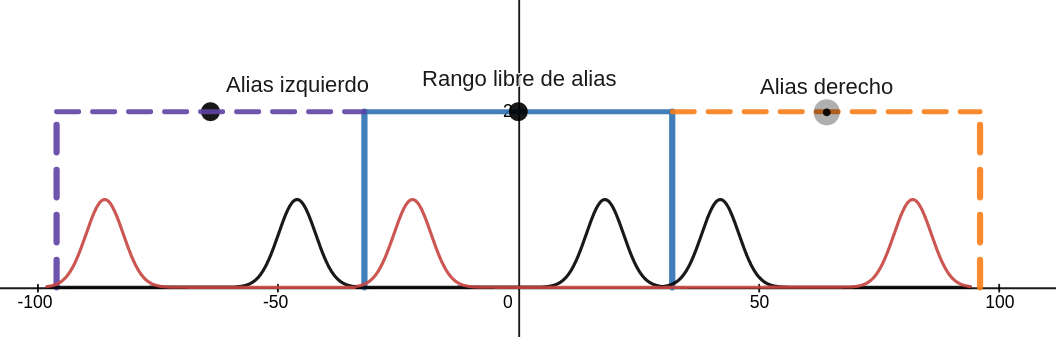

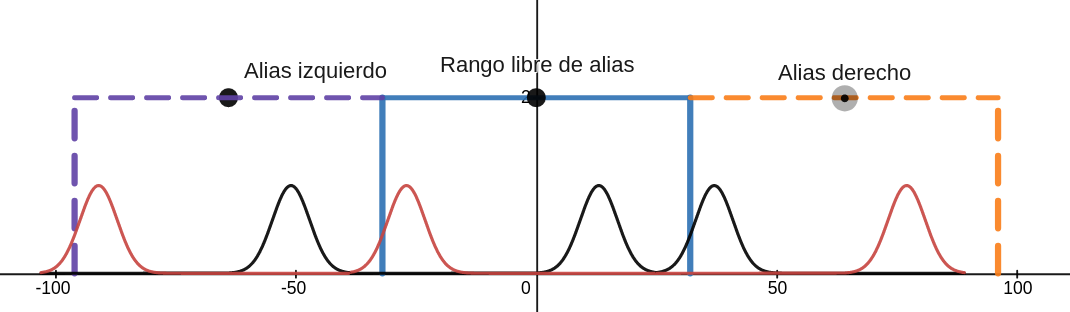

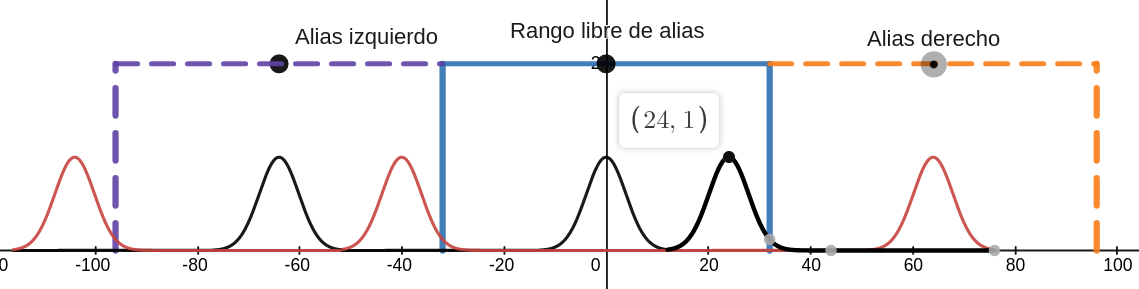

La señal de la izquierda queda centrada en 24kHz

**Conclucion **

   Lo que se esta visualizando en la graphica son los alias!! Finalmente ambas partes se suman y generan la graphica final. 

plot(freq,abs(ttof(sig_recover)))

## **FILTRADO**

Finalmente hacemos un filtro pasabajas para filtrar la señal esperada. Este filtro es demostrativo dado que se esta tomando un pulso cuadrado, pero en realidad deberia ser algo mas suave. 

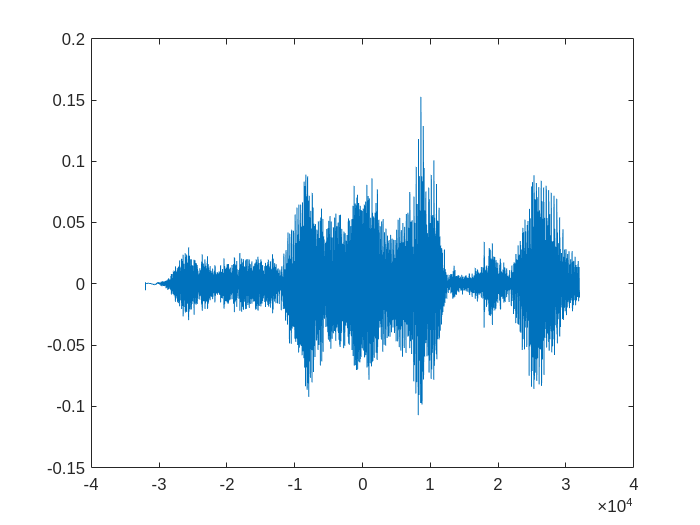

filtrof = zeros(1,length(sig_recover));
filtrof(find(freq==-8000):find(freq==8000))=1;
% multiplicamos por el filtro en el dominio de la frecuencia
sig_filtered = ttof(sig_recover).*filtrof;
%regresamos la señal al dominio del tiempo
sig_filtered = real(ftot(sig_filtered));
sound(sig_filtered,kps_64);
plot(freq,sig_filtered);